Load the image of the heart. 

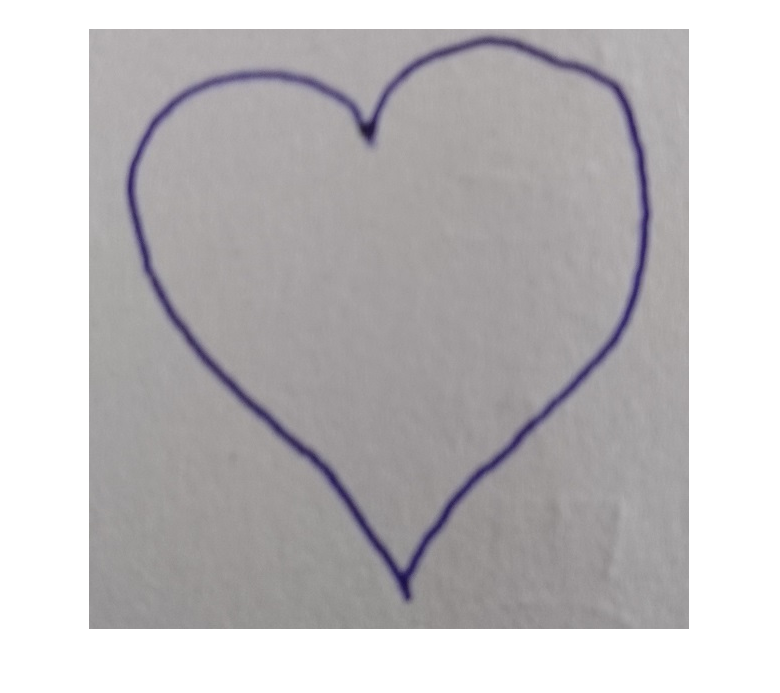

I = imread('heart.jpg');
imshow(I)


min(min(I(:,:,3)))

ans = uint8
51

max(max(I(:,:,3)))

ans = uint8
187

I(502,277,:)

ans = 1×1×3 uint8 array
ans(:,:,1) =

   66


ans(:,:,2) =

   57


ans(:,:,3) =

   100


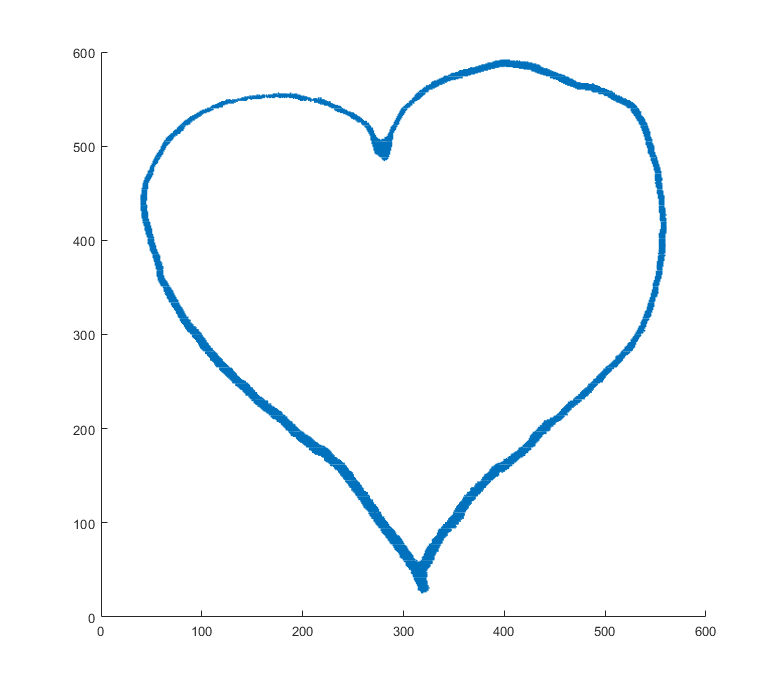


[row,col,v]=find(I(:,:,3)<130); %try 100,120,130,140
scatter(col,600-row,1)

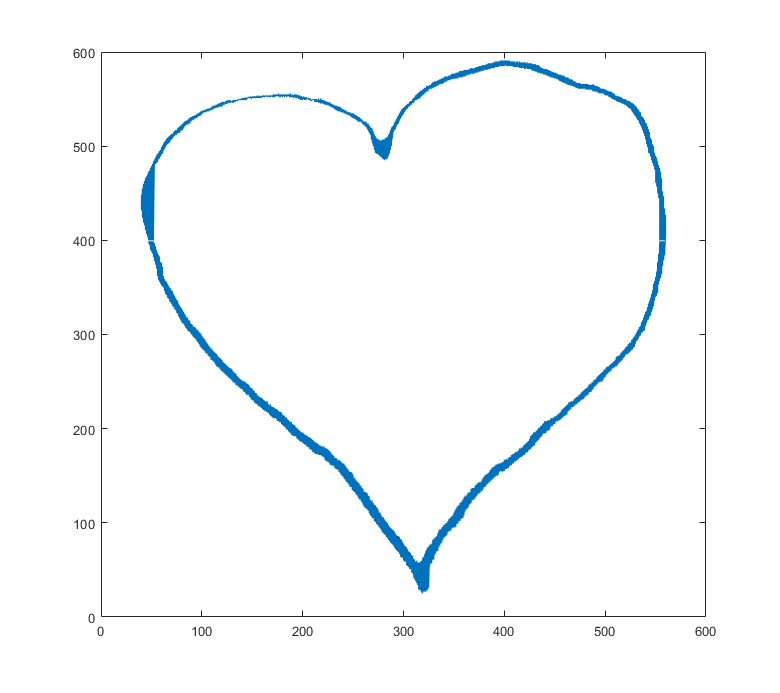

row=600-row;
col=[col(row<400);flip(col(row>=400))];
row=[row(row<400);flip(row(row>=400))];
plot(col,row)

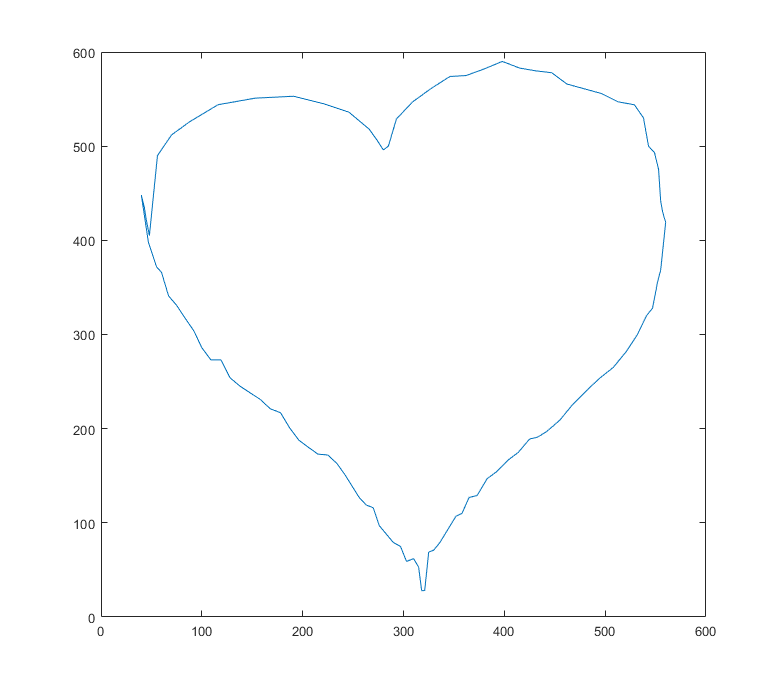

indexes = round(linspace(1,length(col),100));
X = col(indexes);
Y = row(indexes);
X = [X; X(1)];
Y = [Y; Y(1)];
plot(X,Y)

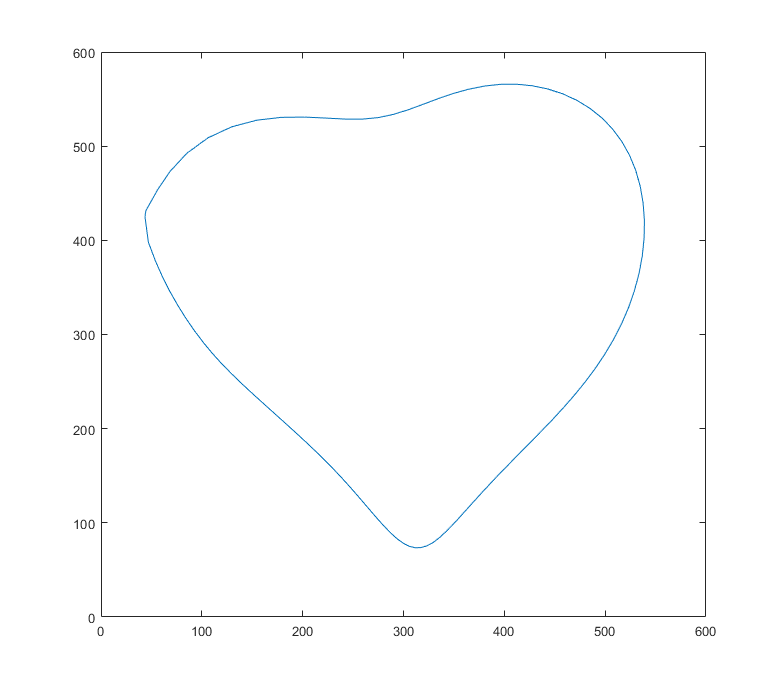

[XX,YY]=decastel(X,Y,100);
plot(XX,YY)

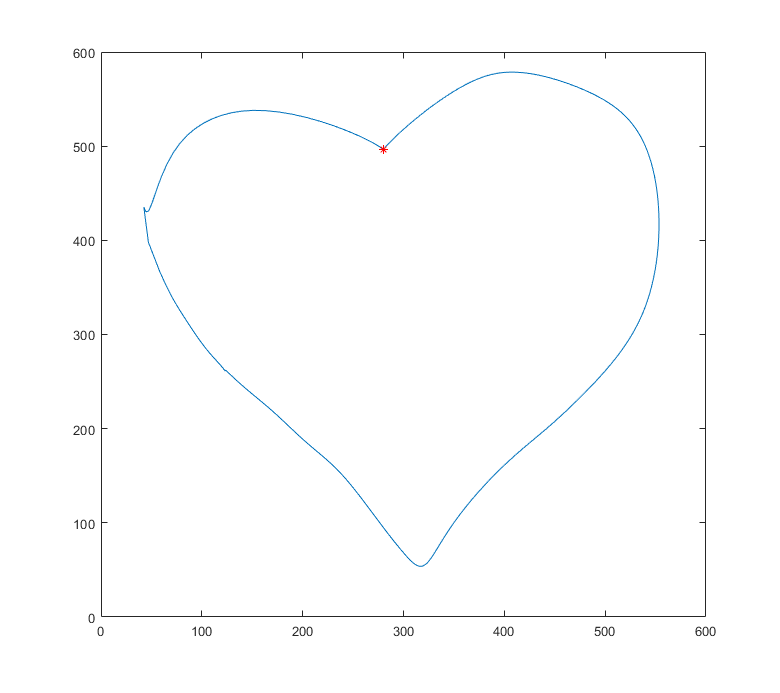

%NURBS
P = [X';Y'];
p = 50;
n= length(X)-1;
l=n+1-p;
T=[zeros(1,p) 0:l l*ones(1,p)];
T=T/l;
W = [ones(1,length(X))*0.1];
W(86) = 10;
tt = linspace(0,1,1000);
[X_n,Y_n]=nurbs(T,P,W,p,tt);
plot(X_n,Y_n,X(86),Y(86),"r*")